parameters2
    initial_condns
        C1_p            = y(:,1:N_p);
        C1_n            = y(:,N_p+1:N_p+N_n);
        C2_p            = y(:,N_p+N_n+1:2*N_p+N_n);
        C2_m            = y(:,2*N_p+N_n+1:2*N_p+N_m+N_n);
        C2_n            = y(:,2*N_p+N_m+N_n+1:2*N_p+N_m+2*N_n);
        P1_p            = y(:,2*N_p+N_m+2*N_n+1:3*N_p+N_m+2*N_n);
        P1_n            = y(:,3*N_p+N_m+2*N_n+1:3*N_p+N_m+3*N_n);
        P2_p            = y(:,3*N_p+N_m+3*N_n+1:4*N_p+N_m+3*N_n);
        P2_m            = y(:,4*N_p+N_m+3*N_n+1:4*N_p+2*N_m+3*N_n);
        P2_n            = y(:,4*N_p+2*N_m+3*N_n+1:4*N_p+2*N_m+4*N_n);
        C3_p            = y(:,4*N_p+2*N_m+4*N_n+1:5*N_p+2*N_m+4*N_n);
        C3_n            = y(:,5*N_p+2*N_m+4*N_n+1:5*N_p+2*N_m+5*N_n);
        T_p             = y(:,5*N_p+2*N_m+5*N_n+1:6*N_p+2*N_m+5*N_n);
        T_s             = y(:,6*N_p+2*N_m+5*N_n+1:6*N_p+3*N_m+5*N_n);
        T_n             = y(:,6*N_p+3*N_m+5*N_n+1:6*N_p+3*N_m+6*N_n);
%Surface plot for Temperature
figure
times = 42;
t_n = 301*T_n(times,:);  
t_p = 301*T_p(times,:);
t_s = 301*T_s(times,:);
t_n_1 = reshape(t_n, [2, 21]);
t_p_1 = reshape(t_p, [2, 21]);
t_s_1 = reshape(t_s, [2,7]);
temp = [t_p_1 t_s_1 t_n_1]

temp =   301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420
  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4421  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420  301.4420


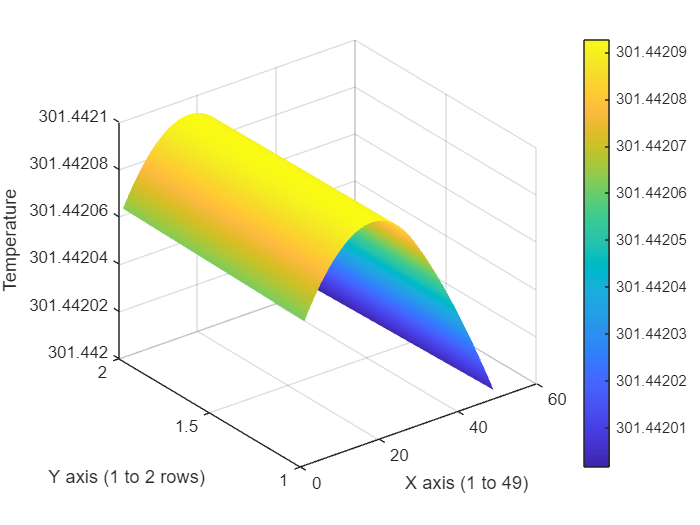

[X, Y] = meshgrid(1:49, [1,2]);
surf(X, Y, temp)
xlabel('X axis (1 to 49)');
ylabel('Y axis (1 to 2 rows)');
zlabel('Temperature');
shading interp;
colorbar;

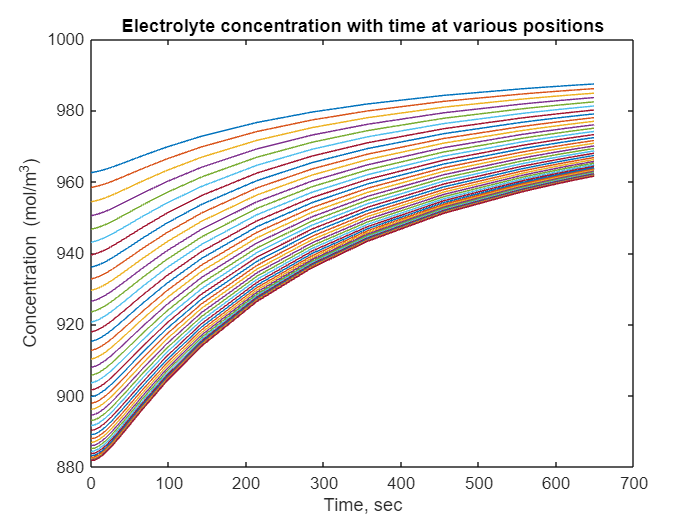

%Electrolyte concentration in negative electrode variation with time 
 figure
 plot(t,[C2_n]*Ce_sc)
 xlabel('Time, sec')
 ylabel('Concentration (mol/m^3)')
 title('Electrolyte concentration with time at various positions')

 %Idea is Expand y by adding new new columns by defining new concentrations
 %of C2_n and T_n_new